clear all;
opengl('save', 'software');
% h5FileStr = 'G:\My Drive\Research\Projects\Paper 2\Data\EEA List\20080326.001_bc_15sec-energyFlux.h5';
% h5FileStr = 'G:\My Drive\Research\Projects\Paper 2\Data\Temp\20101018.001_bc_2min-energyFlux.h5';
h5FileStr = 'G:\My Drive\Research\Projects\Paper 2\Data\Temp\20080326.001_bc_15sec-energyFlux_v85.h5';
omniH5FileStr = 'G:\My Drive\Research\Projects\Data\omni.h5';

## Load data

dascData = get_2D_plot_inputs_time_independent(h5FileStr,...
    'plotModeStr','OpticalImage');

pfisrData = get_2D_plot_inputs_time_independent(h5FileStr,...
    'plotModeStr','EnergyFluxMap');

PFISR Energy Flux Map projected at 159.1233      150.3302      142.2709      134.9451      128.3525       122.493      118.0987       114.437      111.5078      108.5787      106.3819      104.1853      101.9887      99.79217      97.59572      95.39934      93.20303      91.00681      88.81065      86.61457      83.68657      81.49065      78.56288      76.36713      73.43958      70.51216      68.31669       65.3895      62.46244      60.26723 km



energySlice = 100; %keV

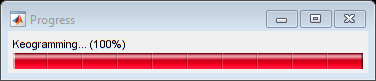

dascImage = permute(h5read(h5FileStr,'/DASC/ASI'),[3 2 1]);
[dascKeo,dascLat,meridian] = create_keogram(dascImage,dascData.latitude,dascData.longitude);

pfisrImage = permute(h5read(h5FileStr,'/energyFluxFromMaxEnt/energyFlux'),[3 2 1]);

[pfisrImage150,pfisrLat150,pfisrLon150,projAlt150] = get_pfisr_energy_slice(pfisrImage,pfisrData,150,100); 
[pfisrKeo150,pfisrPar150] = create_keogram(pfisrImage150,pfisrLat150,pfisrLon150,'meridian',meridian);
[pfisrImage100,pfisrLat100,pfisrLon100,projAlt100] = get_pfisr_energy_slice(pfisrImage,pfisrData,100,100); 
[pfisrKeo100,pfisrPag100] = create_keogram(pfisrImage100,pfisrLat100,pfisrLon100,'meridian',meridian);
[pfisrImage50,pfisrLat50,pfisrLon50,projAlt50] = get_pfisr_energy_slice(pfisrImage,pfisrData,50,100); 
[pfisrKeo50,pfisrPar50] = create_keogram(pfisrImage50,pfisrLat50,pfisrLon50,'meridian',meridian);
[pfisrImage30,pfisrLat30,pfisrLon30,projAlt30] = get_pfisr_energy_slice(pfisrImage,pfisrData,30,100); 
[pfisrKeo30,pfisrPar30] = create_keogram(pfisrImage30,pfisrLat30,pfisrLon30,'meridian',meridian);
multiWaitbar('CLOSEALL');

timeMinStr = '26-Mar-2008 10:45';
timeMaxStr = '26-Mar-2008 11:45';

totalPanelNo=5;
clf;
hFig=figure(1);

p = create_panels(hFig,'totalPanelNo',totalPanelNo,'margintop',4,'panelSize',25);

q=p(1);

q(1).select();
colormap(gca,'viridis');
ax=plot_2D_time_series(dascData.time,dascLat,dascKeo,0.25,0,timeMinStr,timeMaxStr);
% label_time_axis(time, true, 1/6,timeMinStr,timeMaxStr);
hold on; 
timeMinIndx = find_time(pfisrData.time,'26-Mar-2008 11:05');
timeMaxIndx = find_time(pfisrData.time,'26-Mar-2008 11:30');
peakLatitude150 = find_peak_latitude(pfisrKeo150,pfisrPar150);
peakLatitude100 = find_peak_latitude(pfisrKeo100,pfisrPag100);
peakLatitude50 = find_peak_latitude(pfisrKeo50,pfisrPar50);
peakLatitude30 = find_peak_latitude(pfisrKeo30,pfisrPar30);
plot(pfisrData.time(timeMinIndx:timeMaxIndx),peakLatitude150(timeMinIndx:timeMaxIndx),'b');
plot(pfisrData.time(timeMinIndx:timeMaxIndx),peakLatitude100(timeMinIndx:timeMaxIndx),'g');
plot(pfisrData.time(timeMinIndx:timeMaxIndx),peakLatitude50(timeMinIndx:timeMaxIndx),'y');
plot(pfisrData.time(timeMinIndx:timeMaxIndx),peakLatitude30(timeMinIndx:timeMaxIndx),'red');


caxis([300 400]);
axPos = get(gca, 'position');
c = colorbar('eastoutside');


set(gca,'position',axPos);

% reducing color bar thickness
cPos=get(c,'Position');
cPos(3)=0.2*cPos(3);
set(c, 'Position',cPos);
ylim([64.9 65.6]);

q(2).select();
plot_pfisr_energy_keogram(pfisrKeo150,pfisrPar150,pfisrData,false,timeMinStr,timeMaxStr);
ylabel('150 keV');

q(3).select();
plot_pfisr_energy_keogram(pfisrKeo100,pfisrPag100,pfisrData,false,timeMinStr,timeMaxStr);
ylabel('100 keV');

q(4).select();
plot_pfisr_energy_keogram(pfisrKeo50,pfisrPar50,pfisrData,false,timeMinStr,timeMaxStr);
ylabel('50 keV');
q(5).select();
plot_pfisr_energy_keogram(pfisrKeo30,pfisrPar30,pfisrData,true,timeMinStr,timeMaxStr);
ylabel('30 keV');

function [image,lat,lon,projectionAltitude]=get_pfisr_energy_slice(pfisrImage,pfisrData,energySlice,projectionEnergySlice)
    for i=1:1:length(pfisrData.time)
        for ib = 1:1:size(pfisrData.latitude,1)
        image(i,ib) = interp1(pfisrData.zEnergyBin(ib,:),reshape(pfisrImage(i,ib,:),1,[]),energySlice*1000);
        end
    end
    projectionAltitude = calculate_peak_altitude_of_ionization(projectionEnergySlice*1000,pfisrData.timeNeutralAtmosphere);
    for ib = 1:1:size(pfisrData.latitude,1)
        lat(ib) = interp1(pfisrData.zEnergyBin(ib,:),pfisrData.latitude(ib,:),projectionEnergySlice*1000);
        lon(ib) = interp1(pfisrData.zEnergyBin(ib,:),pfisrData.longitude(ib,:),projectionEnergySlice*1000);
    end
end

function plot_pfisr_energy_keogram(pfisrKeo,pfisrLat,pfisrData,setLabelTime,timeMinStr,timeMaxStr)
    pfisrKeo(isnan(pfisrKeo))=10^6;
    pfisrKeo(pfisrKeo<=0) = 10^6;
    colormap(gca,'inferno');
    plot_2D_time_series(pfisrData.time,pfisrLat,log10(pfisrKeo),0.5,0,timeMinStr,timeMaxStr);
    if setLabelTime==true
        label_time_axis(pfisrData.time, true, 1/8,timeMinStr,timeMaxStr);
    end
    axPos = get(gca, 'position');
    c1 = colorbar('eastoutside','Limits',[7 10]);
    set(gca,'position',axPos);
    % set(ax1,'YLim',get(ax,'YLim'));
    % reducing color bar thickness
    cPos=get(c1,'Position');
    cPos(3)=0.2*cPos(3);
    set(c1, 'Position',cPos);
    ylim([64.9 65.6]);
end

function peakLatitude=find_peak_latitude(keo,lat)
    [~,index] = max(keo,[],1);
    peakLatitude = movmean(lat(index),10); 
end

